# Escalon grande

## Test 30 A

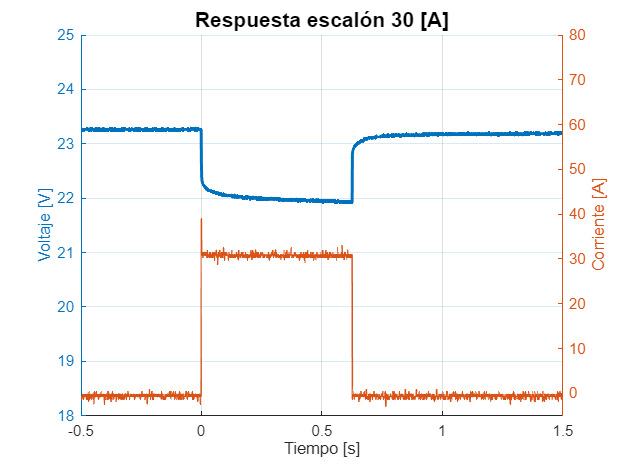

clear all;
clf;
clc;

rSense = 1.5e-3;

data = readmatrix("2025-11-27_Battery/scope_1.csv", 'NumHeaderLines', 2);
time_1      = data(:, 1);
volt_1      = data(:, 2);
current_1      = data(:, 3);
current_1      = current_1 / rSense; %Rsense corriente

%Figura 1
clf %% clean figure
figure(1)
hold on 
grid on
yyaxis left
plot(time_1,volt_1,'LineStyle', '-', 'LineWidth', 2)
ylim([18 25]);
ylabel("Voltaje [V]");
yyaxis right
plot(time_1,current_1,'LineStyle', '-', 'LineWidth', 1)
ylim([-5 80]);
ylabel("Corriente [A]");

%Main config
xlabel("Tiempo [s]");
% xlim([-0.5e-4 1.25e-4])
title("Respuesta escalón 30 [A]",'FontSize',14);
% subtitle(plotSubTitle,'FontSize',8);

%Exportacion
hold off
exportgraphics(gcf,"Figuras/bat_30a.png");


current_av = mean(current_1(503:1120));

## Carga 30A zoom

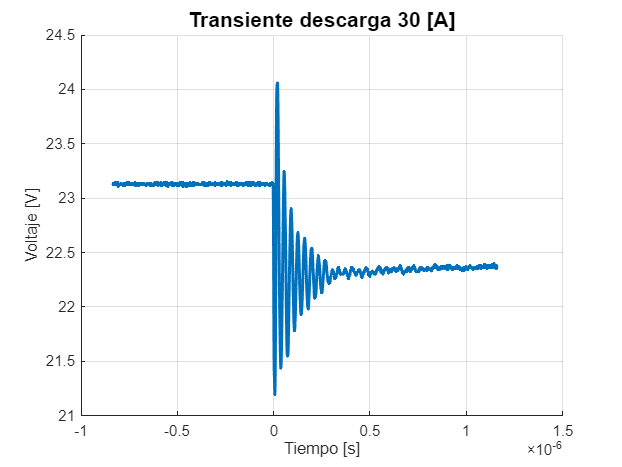

% rSense = 1.5e-3;

data = readmatrix("2025-11-27_Battery/scope_4.csv", 'NumHeaderLines', 2);
time_1      = data(:, 1);
volt_1      = data(:, 2);
% current_1      = data(:, 3);
% current_1      = current_1 / rSense; %Rsense corriente

%% Figure 2
clf
figure(2)
hold on 
grid on
plot(time_1,volt_1,'LineStyle', '-', 'LineWidth', 2)
% ylim([18 25]);
ylabel("Voltaje [V]");

xlabel("Tiempo [s]");
% xlim([-0.5e-4 1.25e-4])
title("Transiente descarga 30 [A]",'FontSize',14);
% subtitle(plotSubTitle,'FontSize',8);

hold off
exportgraphics(gcf,"Figuras/bat_30a_load.png");


%load
volt_low = mean(volt_1(1:830));
volt_high = mean(volt_1(1140:1300));
volt_diff_0 = volt_high - volt_low;
% volt_diff_0 = 0.80625
R0_0 = abs(volt_diff_0)/current_av;


## Desarga 30A zoom (1)

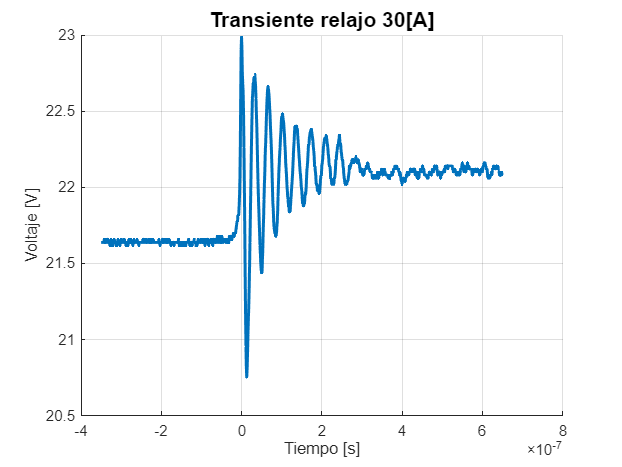


% rSense = 1.5e-3;

data = readmatrix("2025-11-27_Battery/scope_7.csv", 'NumHeaderLines', 2);
time_1      = data(:, 1);
volt_1      = data(:, 2);
% current_1      = data(:, 3);
% current_1      = current_1 / rSense; %Rsense corriente

%% Figure 3
clf
figure(3)
hold on 
grid on
plot(time_1,volt_1,'LineStyle', '-', 'LineWidth', 2)
% ylim([18 25]);
ylabel("Voltaje [V]");

xlabel("Tiempo [s]");
% xlim([-0.5e-4 1.25e-4])
title("Transiente relajo 30[A]" ,'FontSize',14);
% subtitle(plotSubTitle,'FontSize',8);

hold off
exportgraphics(gcf,"Figuras/bat_30a_dsg_1.png");


%dv
volt_low = mean(volt_1(1:320));
volt_high = mean(volt_1(751:1000));
volt_diff_1 = volt_high - volt_low;
% volt_diff = 0.687;

%R0
R0_1 = volt_diff_1/current_av;


## Desarga 30A zoom (2)

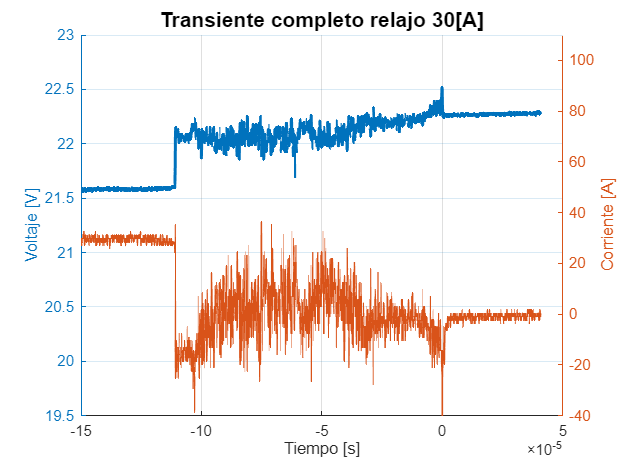

rSense = 1.5e-3;

data = readmatrix("2025-11-27_Battery/scope_8.csv", 'NumHeaderLines', 2);
time_1      = data(:, 1);
volt_1      = data(:, 2);
current_1      = data(:, 3);
current_1      = current_1 / rSense; %Rsense corriente

%% Figure 4
clf
figure(4)
hold on 
grid on
yyaxis left
plot(time_1,volt_1,'LineStyle', '-', 'LineWidth', 2)
ylim([19.5 23]);
ylabel("Voltaje [V]");
yyaxis right
plot(time_1,current_1,'LineStyle', '-', 'LineWidth', 1)
ylim([-40 110]);
ylabel("Corriente [A]");

xlabel("Tiempo [s]");
xlim([-15e-5 5e-5])
title("Transiente completo relajo 30[A]",'FontSize',14) ;
% subtitle(plotSubTitle,'FontSize',8);

hold off
exportgraphics(gcf,"Figuras/bat_30a_dsg_2.png");


%releax
volt_low = mean(volt_1(1:400));
volt_high = mean(volt_1(1600:2000));
volt_diff_2 = volt_high - volt_low;
R0_2 = volt_diff_2/current_av;

volt_dif = [volt_diff_0 volt_diff_1 volt_diff_2]

volt_dif =    -0.8142    0.4640    0.6939


R0       = [R0_0        R0_1        R0_2]

R0 =     0.0264    0.0151    0.0225




%Si transferencia máxima
Imax = 25.2 ./ (R0.*2)

Imax =   476.5967  836.2303  559.2191


# Escalon pequeño y reposo

## Descarga

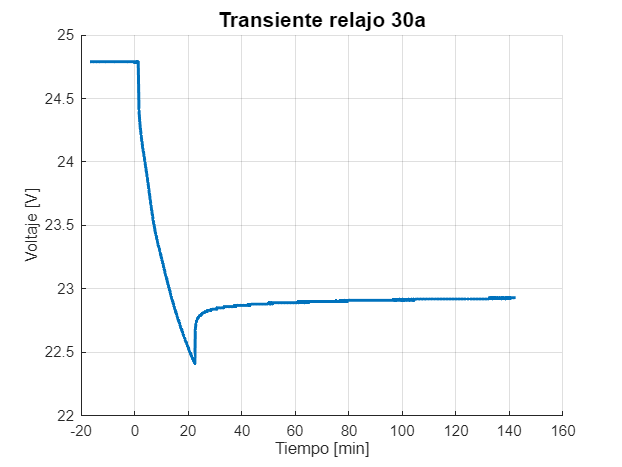

% clear all;
clf;
clc;

data = readmatrix("Battery response/bat_unit.csv", 'NumHeaderLines', 1);
x1      = data(:, 1);
min      = x1/(60);
y1      = data(:, 2);
% ampere_1    = data(:, 3);

second = x1;
Volt = y1;
% y2 = 0.66 * 1000 * Ampere;
% 
% plot(x1,y1,'o')
% plot(x1,y2)

figure(1)
hold on 
grid on
% yyaxis left
plot(min,y1,'LineStyle', '-', 'LineWidth', 2)
% ylim([19.5 23]);
ylabel("Voltaje [V]");

xlabel("Tiempo [min]");
% xlim([-15e-5 5e-5])
title("Transiente relajo 30a", 'FontSize', 14);
% subtitle(plotSubTitle,'FontSize',8);
hold off


% %%%exportgraphics(gcf,"Figuras/bat_long_0.png");


## Descarga +

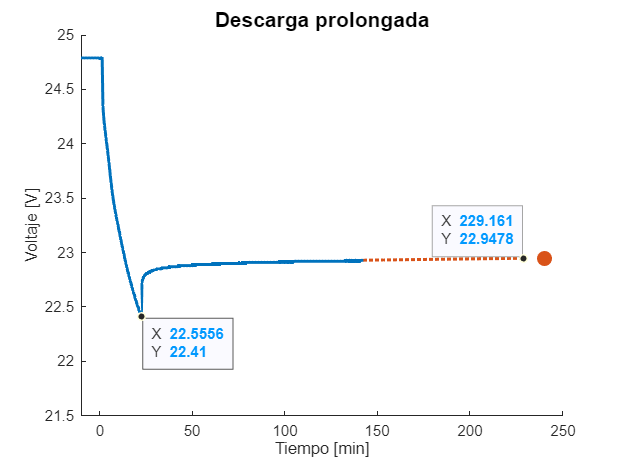

clf

second_2    = linspace(second(end), 60*60*4,    10)/60;
Volt_2      = linspace(Volt(end),   22.95,      10);

p_colour = [0.8500, 0.3250, 0.0980];

hold on
%Original
plot(min,Volt,'LineStyle', '-', 'LineWidth', 2)
%Proyección
plot(second_2(1:end-1),Volt_2(1:end-1),'LineStyle', ':', 'LineWidth', 2, 'Color', p_colour)
%Marcador
plot(second_2(end),Volt_2(end),'.', ...
    'MarkerSize', 30, ...
    'MarkerFaceColor',p_colour, ...
    'MarkerEdgeColor', p_colour, ...
    'Color', p_colour)
% Datatips
ax2 = gca;
chart2 = ax2.Children(2);
datatip(chart2,  240,       22.95);
ax3 = gca;
chart3 = ax3.Children(3);
datatip(chart3,  22.5889,   22.4500, 'Location', 'southeast');
%Configs
ylabel("Voltaje [V]");
ylim([21.5 25])
xlabel("Tiempo [min]");
xlim([-10 250])
title("Descarga prolongada",'FontSize',14);
% subtitle(plotSubTitle,'FontSize',8);

% Arrow
% x1 = [100 150];
% y1 = [23.5 23.5];
% x2 = [100 150];
% y2 = [23.5 23.5];
% 
% % Customizing arrow properties
% arrowStart = [.5, .65]; % Starting point of the arrow
% arrowEnd = [.425, .425]; % Length and direction of the arrow
% 
% arrowHandle = annotation('arrow', arrowStart, arrowEnd);
% arrowHandle.Color = p_colour;
% arrowHandle.LineWidth = 2;
% arrowHandle.HeadStyle = 'cback2';

hold off
exportgraphics(gcf,"Figuras/bat_long.png");


% x1_start_index = find(x1==0.8675);
% x1_value = x1(x1_start_index)
% y1_value = y1(x1_start_index);
% 
% 
% x1p = x1(x1_start_index:end) - x1_value + realmin("single");
% y1p = y1(x1_start_index:end);
% 
% x1pp = [x1p ; 60*5];      %Tiempo de ss
% y1pp = [y1p ; 23.1558];    %Tension de ss
% 
% 
% plot(x1pp,y1pp,'o')
% 
% xlim([0 301])
% ylim([21.5 23.5])
% 
% find(x1pp==300)
% y1pp(find(x1pp==300))



## Ztaz:

### R0 y R1

% R0_2 = 22.5e-3;
R0 = R0_1

R0 = 0.0151

Ix = 4;

Vf = 22.95;
Vo = 22.41;
dV = Vf-Vo

dV = 0.5400


% dV = (R0+R1)I
R1 = (dV/Ix) - R0

R1 = 0.1199


%5,4,3,2 tau%
Vo + dV*0.993;
Vo + dV*0.982;
Vo + dV*0.95;
Vo + dV*0.9502

ans = 22.9231

Vo + dV*0.865;
%22.923%

### Interpolación

volt_mean = movmean(Volt(16000:30005),1024);
% ind = volt_mean == 22.9150 
%% 3657
% ind = volt_mean == 22.9250 
%% 10623
min_int = linspace(min(18000+3657), min(18000+10623), 1000);
volt_int = linspace(22.9150, 22.9250 , 1000);

%% min 129.066045211879
s_sec = 129.066045211879*60

s_sec = 7.7440e+03

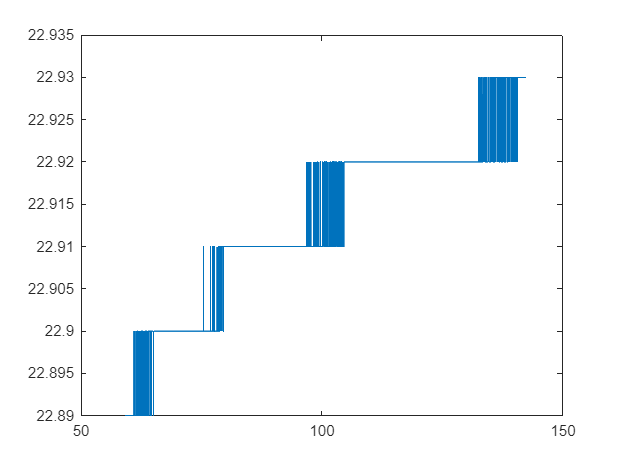


%Grafico para rango
clf;
plot(min(13000:30005),Volt(13000:30005))
ylim([22.89 22.935])

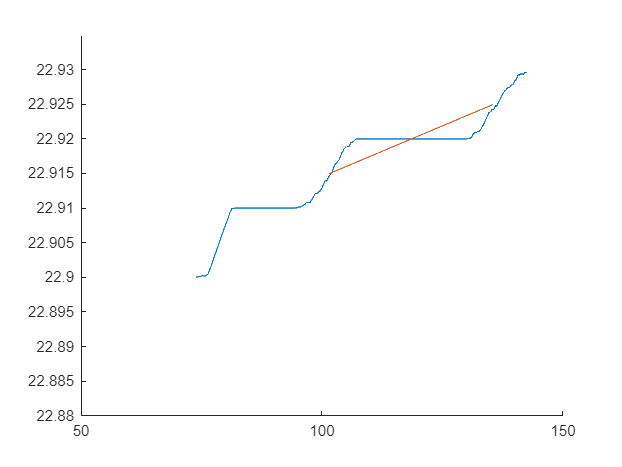



%Grafico representativo
clf;
hold on
plot(min(16000:30005), volt_mean)
plot(min_int, volt_int)

ylim([22.88 22.935])
xlim([50 150])
hold off

### C1

to = 22.5556*60;
% tf = 110*60;
tf = 7764;

dt = tf - to

dt = 6.4107e+03

dV

dV = 0.5400


% tau = R1*c1
% tau = dt /3
C1 = dt/(3*R1) %1554%

C1 = 1.7817e+04


% tf = find(min == 110)
% Volt(find(min == 110))